# MID-TERM PROJECT

Sotgia Francesca - 513067

The aim of the project is to devolp a fuzzy inference system for tumor segmentation in MR images with genetic algorithms-based rules selection. 

The goal is to detect the location of the brain tumor in MRIs.

In MRIs the brain tumor can appear as regions with altered characteristics, which can be identified through segmentation. 

clear 
close all
clc

## Data loading 

The first step is to load the data.

### Download BraTS

Start by downloading the BraTS dataset, which contain MR images of patients.

For each patient the dataset contains a volume of the brain with size 240x240x152 and a mask (called label) with is the gold standard, i.e. what we want to achieve with this project.

imageDir = fullfile(tempdir,"BraTS");
filename = matlab.internal.examples.downloadSupportFile(...
    "vision","data/sampleBraTSTestSetValid.tar.gz");
untar(filename,imageDir);

imageDir = fullfile(tempdir, "BraTS", "sampleBraTSTestSetValid", "imagesTest");
labelDir = fullfile(tempdir, "BraTS", "sampleBraTSTestSetValid", "labelsTest");

imageFiles = dir(fullfile(imageDir, "*.mat")); 
labelFiles = dir(fullfile(labelDir, "*.mat"));

Extract names of the files.

imageSubjects = erase({imageFiles.name}, ".mat");
labelSubjects = erase({labelFiles.name}, ".mat");

Visualize possible subjects.

disp(imageSubjects)

    {'BraTS446'}    {'BraTS447'}    {'BraTS455'}    {'BraTS461'}    {'BraTS463'}



disp(labelSubjects)

    {'BraTS446'}    {'BraTS447'}    {'BraTS455'}    {'BraTS461'}    {'BraTS463'}



### Select a patient

Consider patient BraTS447 for the train.

dataFileName = fullfile(imageDir, "BraTS447");
labelFileName = fullfile(labelDir, "BraTS447");

Load the data of the patient.

data = load(dataFileName); 
label = load(labelFileName);

Extract a slice out of a 3D image.

Extract a slice means to get a 2D image out of a 3D one. It is better to chose a slice in the middle of the brain, since it is more probable to find a tumor in that area.

sliceNumber = 70;
data = data.cropVol(:,:,sliceNumber,1);  
label = label.cropLabel(:,:,sliceNumber);

### Visualize the image 

Visualize the brain slice to see the location of the tumor in the brain.

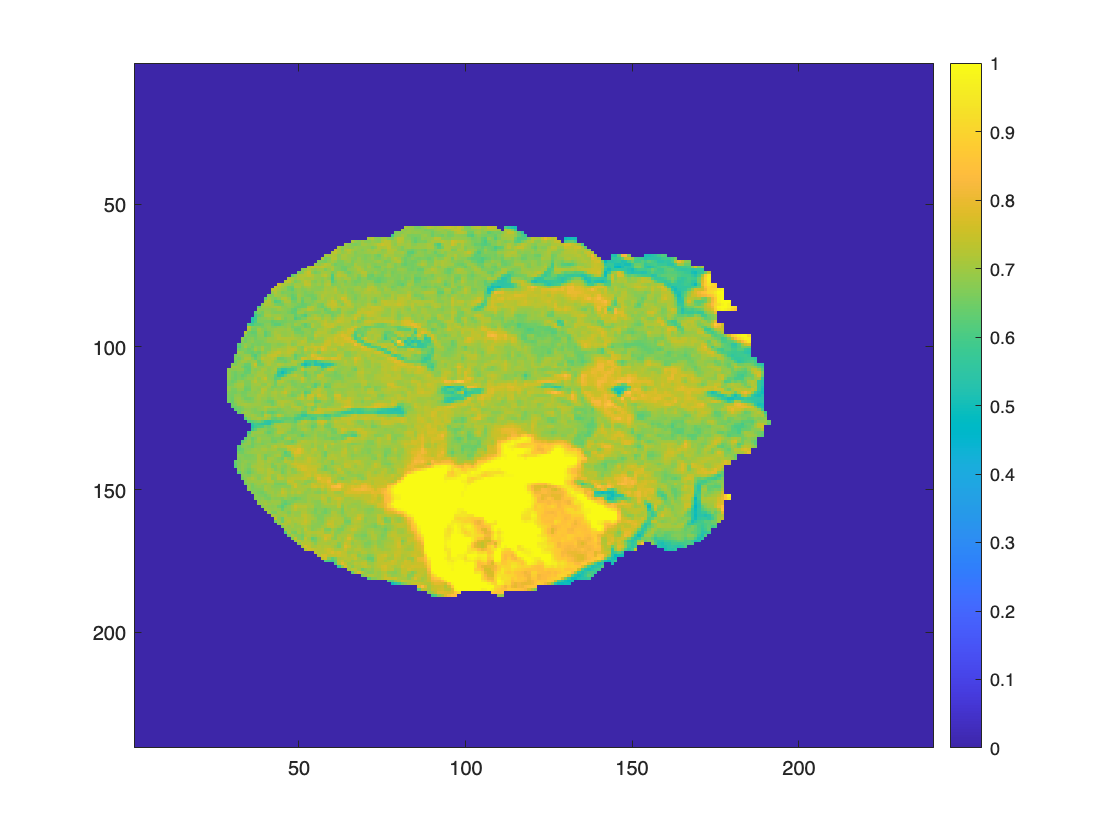

imagesc(data)
colorbar;

### Normalize the image

We want to normalize the image to have all the values in the range [0,1].

To normalize the images we defined a function named *norm_f*, saved in the file 'norm_f.m'.

In this case the values were already in the given range, so the images will result to be identical.

% Normalization
norm_data = norm_f(data);

% Visualization
imagesc(norm_data)
colorbar;

### Visualize the mask

The mask retrieved for the dataset (called '*label*') is the gold standard, which means that it is what we want to achieve.

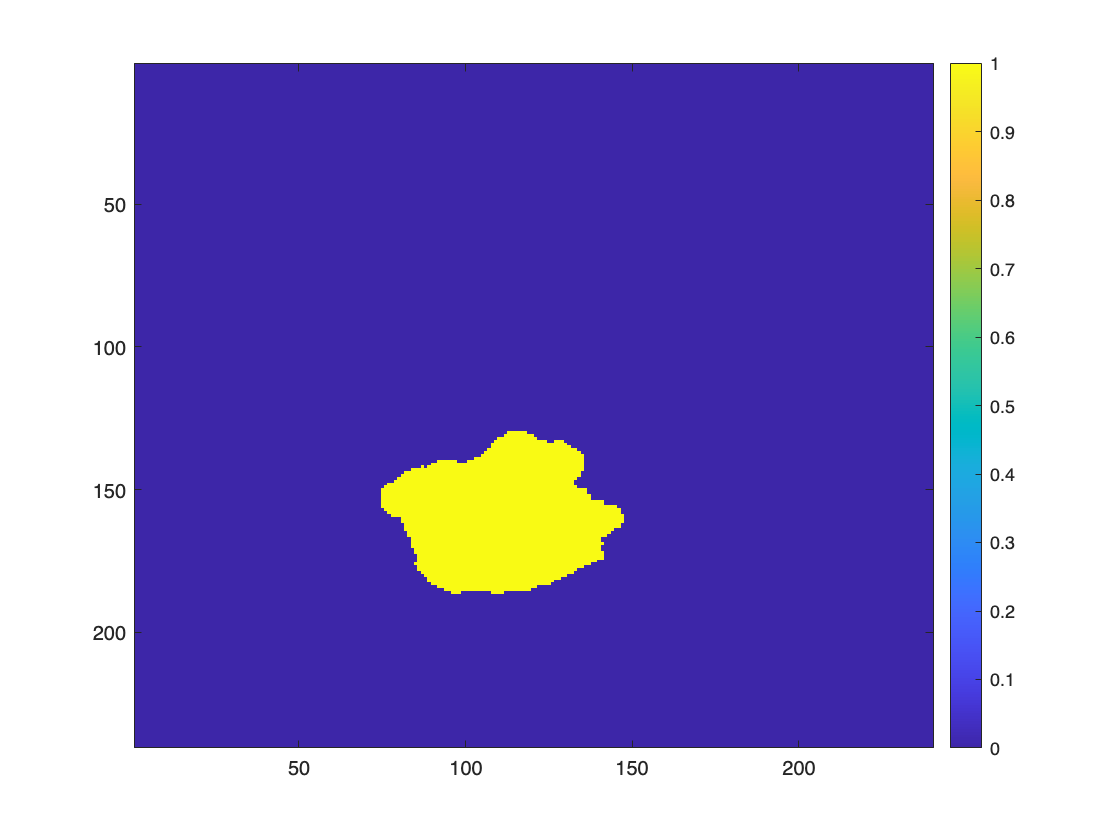

% Visualize
imagesc(label)
colorbar;

## PHASE 1: development of the Fuzzy Inference System

In this phase we develop a Fuzzy Inference System (FIS).

We started by defining multiple features that are meaningful for image processing and segmentation. These features will be then used in a fuzzy inference system to dected the area of the tumor.

To do so, we defined a sliding widow that will apply the functions to every pixel.

Finally, we created different fuzzy rules to infer tumor segmentation based on the selected feaures.

### Define sliding window 

Define a sliding window with dimension 3 x 3.

window_dim = [3 3];

#### **Mean value**: 

Define a sliding window that apply to each pixel the mean value of its neighborhood, defined by the dimension of the sliding window.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a mean filter is applied to the image, it is expected to be more blurred and smooth.

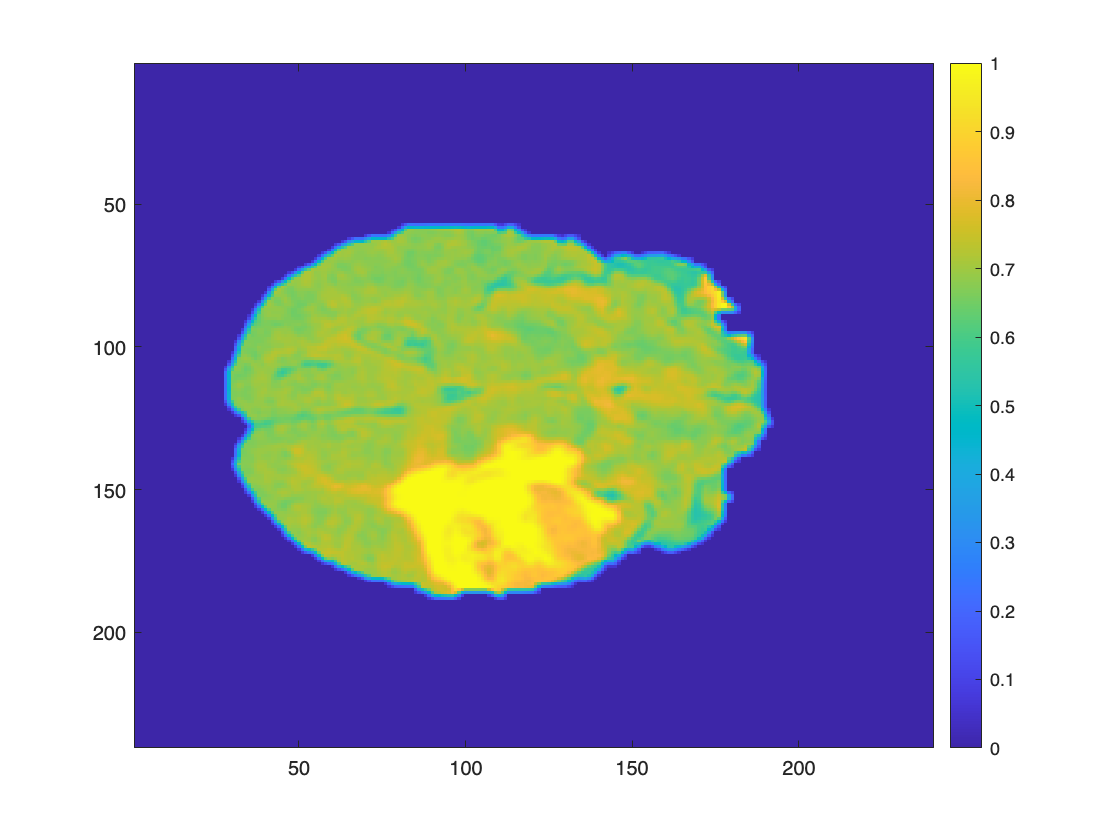

% Apply the sliding window
data_mean = colfilt(data, window_dim, 'sliding', @mean);

% Normalization 
norm_mean = norm_f(data_mean);

% Visualization 
imagesc(norm_mean)
colorbar;

#### **Standard deviation**:

Define a sliding window that apply to each pixel the standard deviation of its neighborhood, defined by the dimension of the sliding window.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a standard deviation filter is applied to the image, it is expected to have a clearer distinction of the edges.

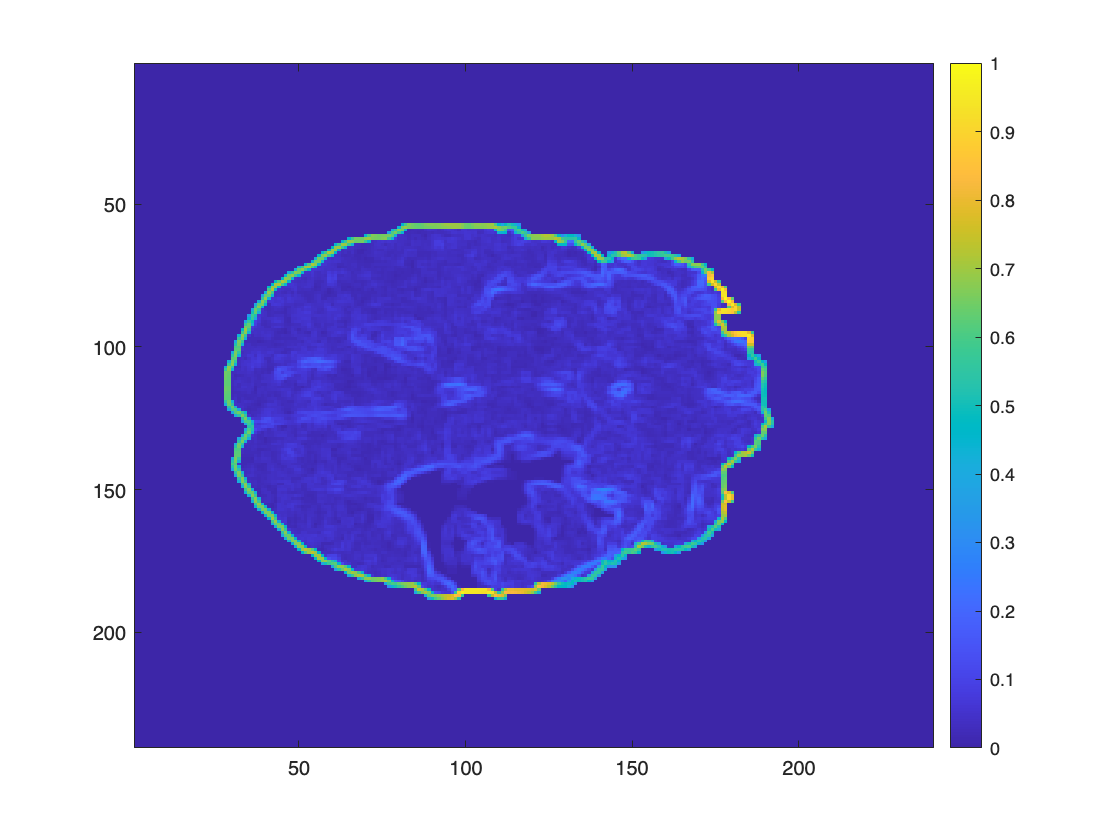

% Apply the sliding window
data_std = colfilt(data, window_dim, 'sliding', @std);

% Normalization
norm_std = norm_f(data_std);

% Visualization
imagesc(norm_std)
colorbar;

#### **Kurtosis**:

Define a sliding window that apply to each pixel the kurtosis value of its neighborhood.

Kurtosis is a statistical measure that refers to the tailedness of a distribution, this means that it describes the shape of the tails; so it provides insights into specific characteristics of a distribution.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a kurtosis filter is applied to the image, it is expected to have lower values in the background with few regions with higher intensity, which would represent the brain.

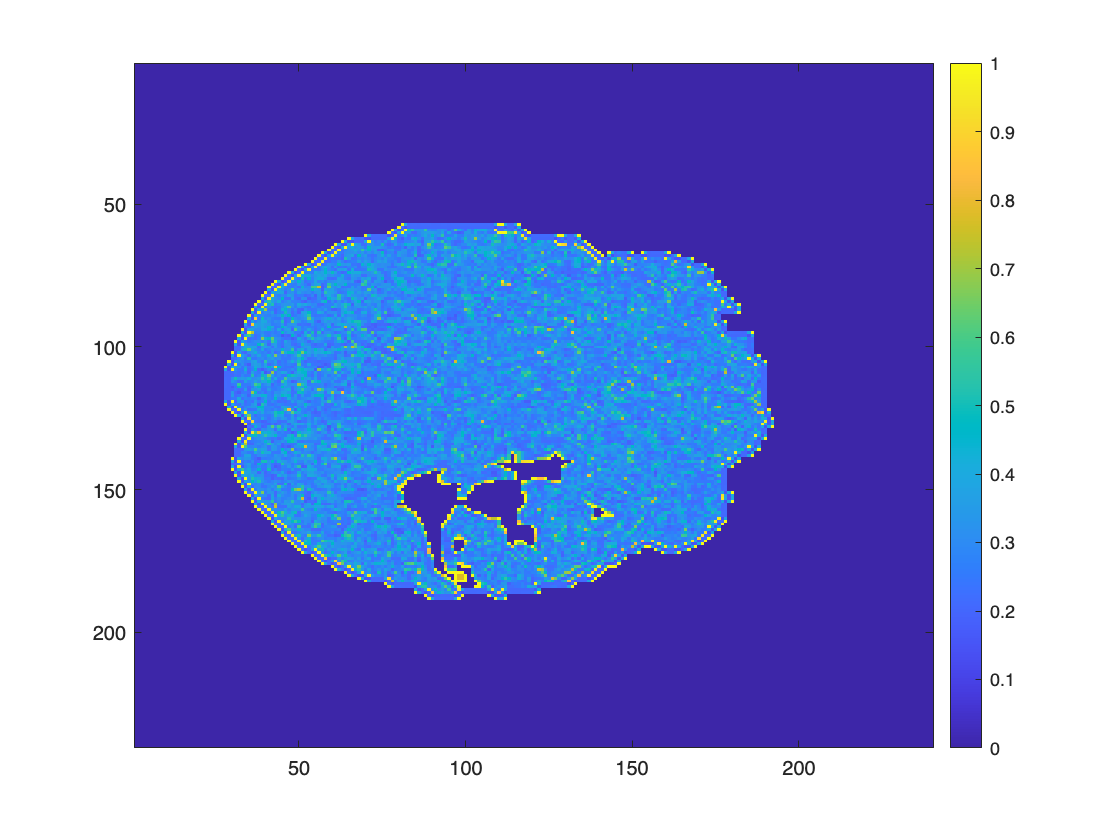

% Apply the sliding window
data_kurtosis = colfilt(data, window_dim, 'sliding', @kurtosis);
data_kurtosis = fillmissing(data_kurtosis, 'constant', 0); % Fill missing values with 0

% Normalization
norm_kurtosis = norm_f(data_kurtosis);

% Visualization
imagesc(norm_kurtosis)
colorbar;

#### **Skewness**:

Define a sliding window that apply to each pixel the skewness value of its neighborhood.

Skewness is a statistical measure that describes the asymmetry of the probability distribution around the mean.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a skewness filter is applied to the image, it is expected to highlight the boundaries.

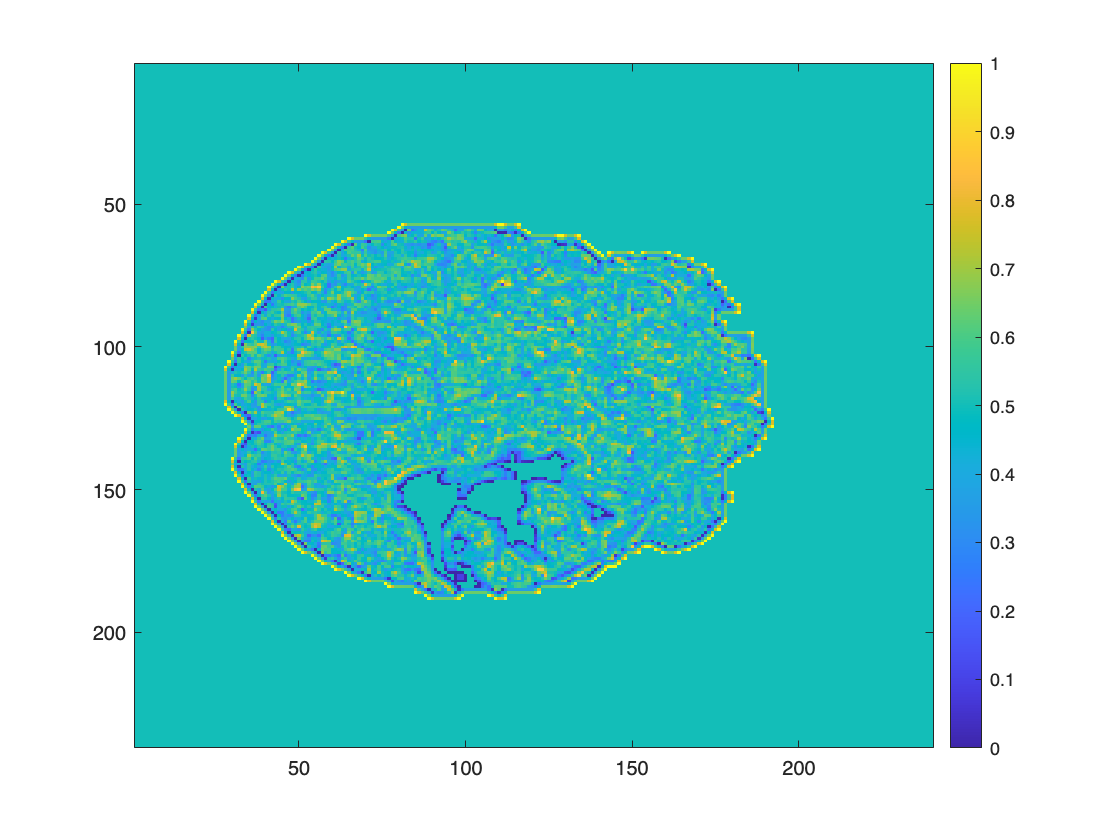

% Apply the sliding window
data_skewness = colfilt(data, window_dim, 'sliding', @skewness);
data_skewness = fillmissing(data_skewness, 'constant', 0);  % Fill missing values with 0

% Normalization
norm_skewness = norm_f(data_skewness);

% Visualization
imagesc(norm_skewness)
colorbar;

#### **Entropy**: 

Apply entropy to the original image.

Entropy, in this framework, describes the uncertainty of a pixel intensity, highlighting textured regions to uniform ones.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a entroy is applied to the image, it is expected to have higher values where the tissue is more uniform.

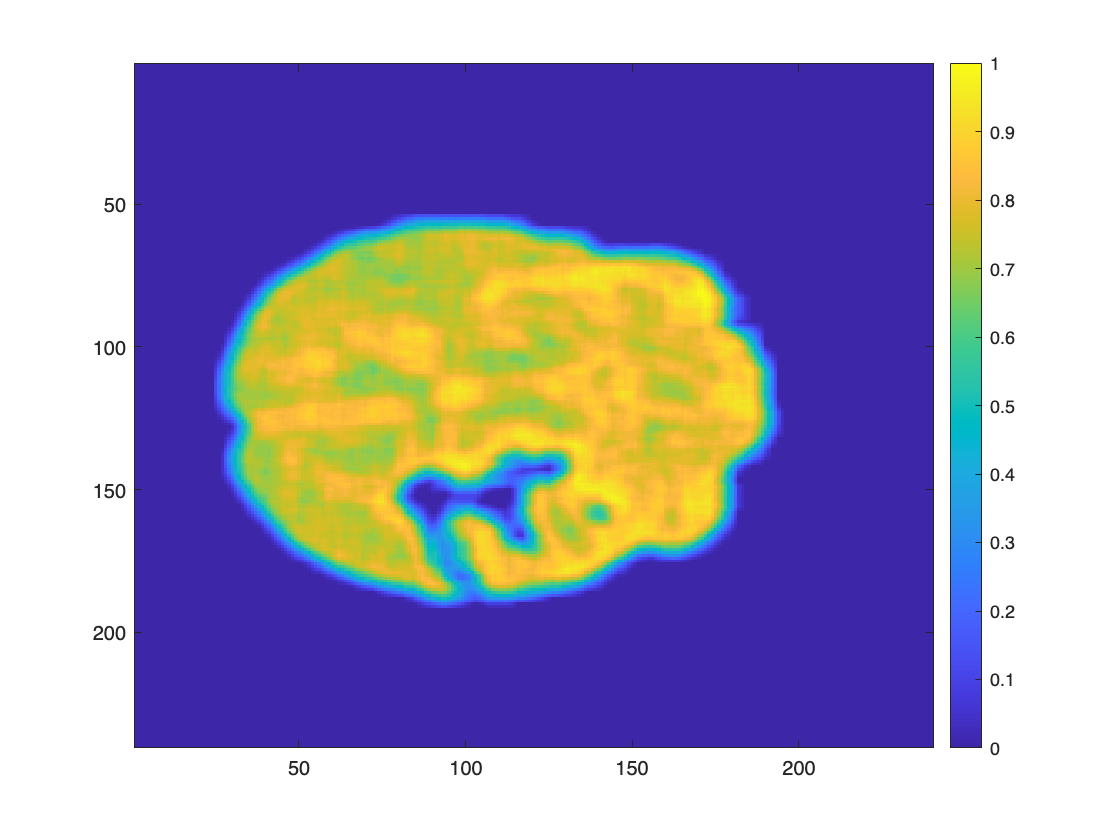

data_entropy = entropyfilt(data);

% Normalization
norm_entropy = norm_f(data_entropy);

% Visualization
imagesc(norm_entropy)
colorbar;

#### Energy:

Define a sliding window that apply to each pixel the energy value of its neighborhood.

Energy, in this framework, refers to the uniformity of an image.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a energy filter is applied to the image, it is expected to have higher values for the tumor, middle and smoother values for the brain tissue and lower values for the background.

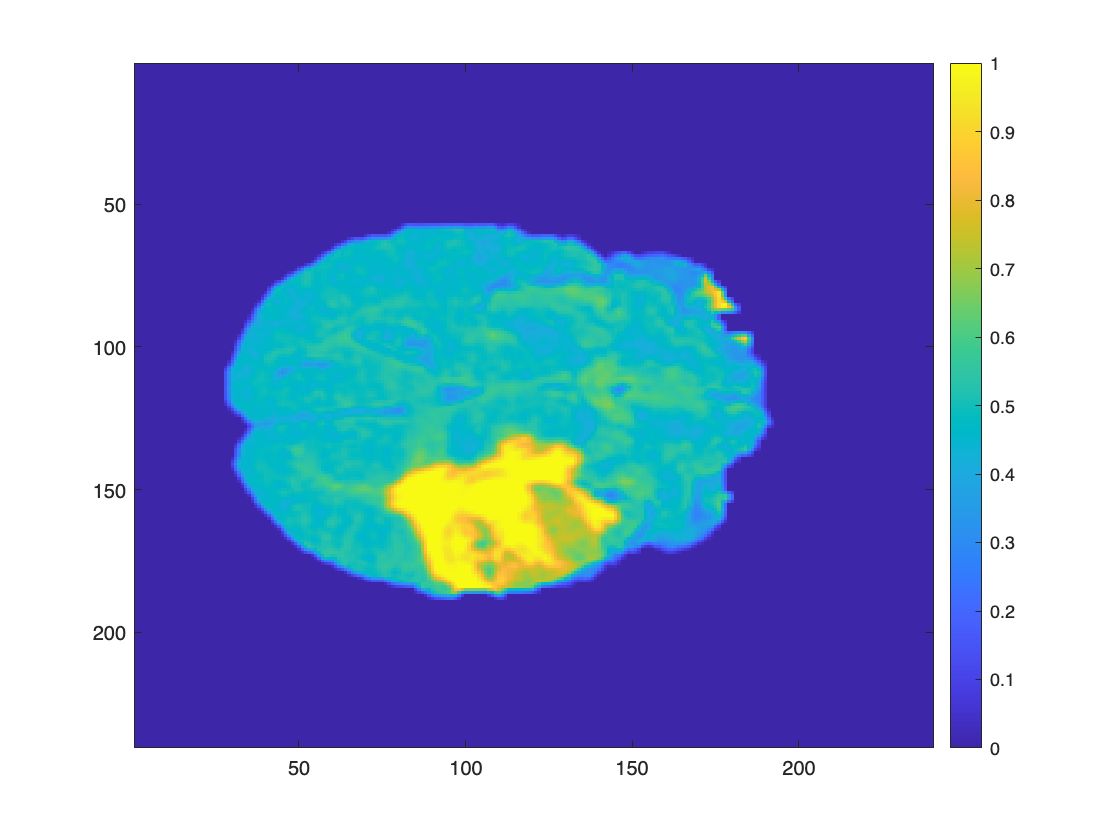

% Define the energy function
energy_f = @(x) sum(x.^2);

% Apply the sliding window
data_energy = colfilt(data, window_dim, 'sliding', energy_f);

% Normalization
norm_energy = norm_f(data_energy);

% Visualization
imagesc(norm_energy)
colorbar;

#### Contrast: 

Apply contrast to the brian image.

Contrast is the difference of intensity between pixels and regions.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a contrast is applied to the image, it is expected to highlight regions where there is a difference in intensity.

data_contrast = k(data);

% Normalization
norm_contrast = norm_f(data_contrast);

% Visualization
imagesc(norm_contrast)
colorbar;

#### Median:

Define a sliding window that apply to each pixel the median value of its neighborhood.

Median is the value (or set of values) separating the higher half and the lower half of a sample, i.e. it is the value in the middle of a sample.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a madian filter is applied to the image, it is expected to be smoother, while maintaining clear edges.

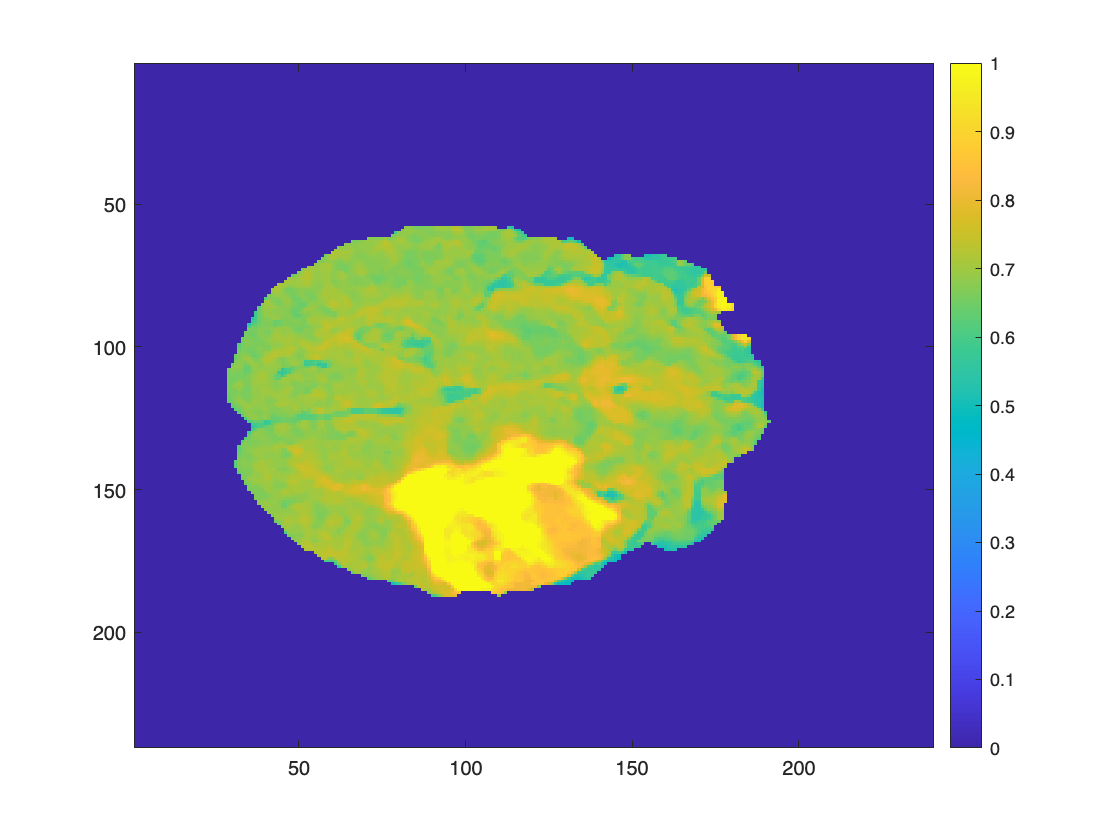

% Apply the sliding window
data_median = colfilt(data, window_dim, 'sliding', @median);

% Normalization
norm_median = norm_f(data_median);

% Visualization
imagesc(norm_median)
colorbar;

#### Harmonic mean:

Define a sliding window that apply to each pixel the harmonic mean value of its neighborhood.

Harmonic mean is the reciprocal of the arithmetic mean of the reciprocals of the numbers. It is more influenced by smaller values w.r.t. the arithmetic mean.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a harmonic mean filter is applied to the image, it is expected to be similar to the mean image but with clearer edges ang higher sensibilty to lower values.

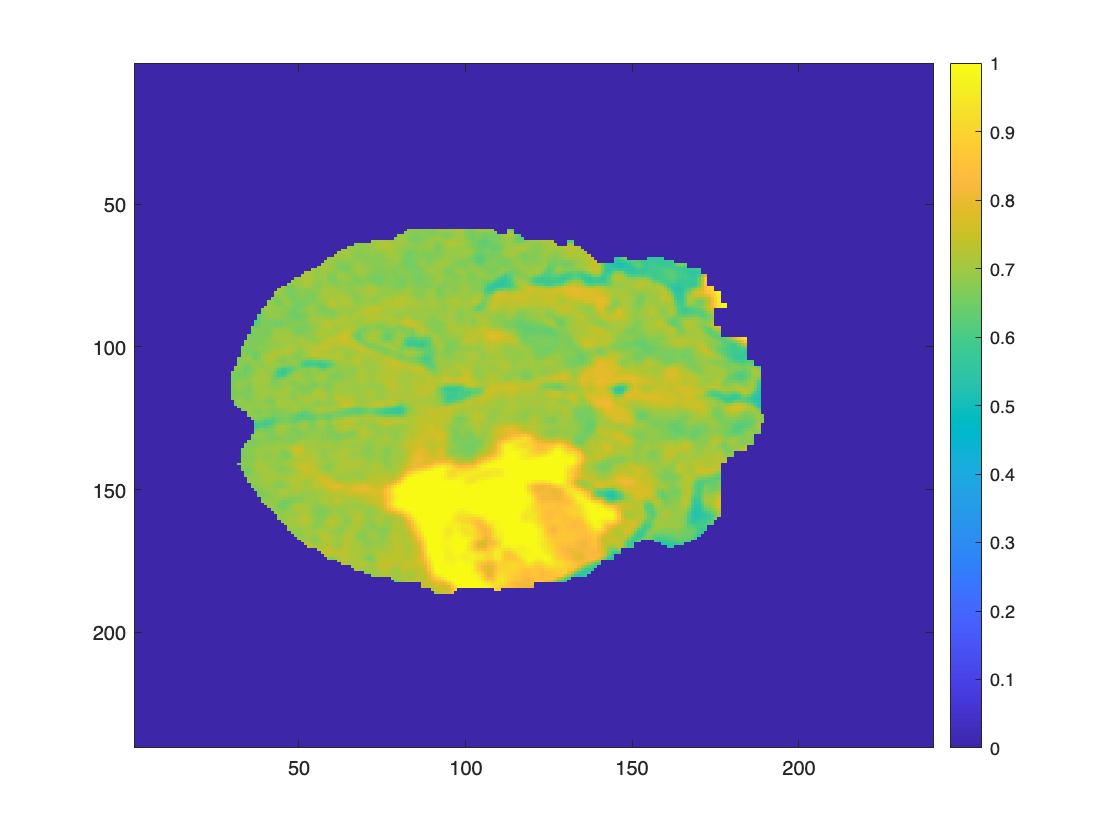

% Apply the sliding window
data_harmmean = colfilt(data, window_dim, 'sliding', @harmmean);

% Normalization 
norm_harmmean = norm_f(data_harmmean);

% Visualization 
imagesc(norm_harmmean)
colorbar;

#### Geometric mean:

Define a sliding window that apply to each pixel the geometric mean value of its neighborhood.

Geometric mean is the n-th root of the product of n numbers. It is less sensible to extreme values w.r.t. arithmetic mean.

Then normalize it to have the values in range [0, 1] and visualize the normalized image.

Since a geometric mean filter is applied to the image, it is expected to be smoother but less influenced by outliers.

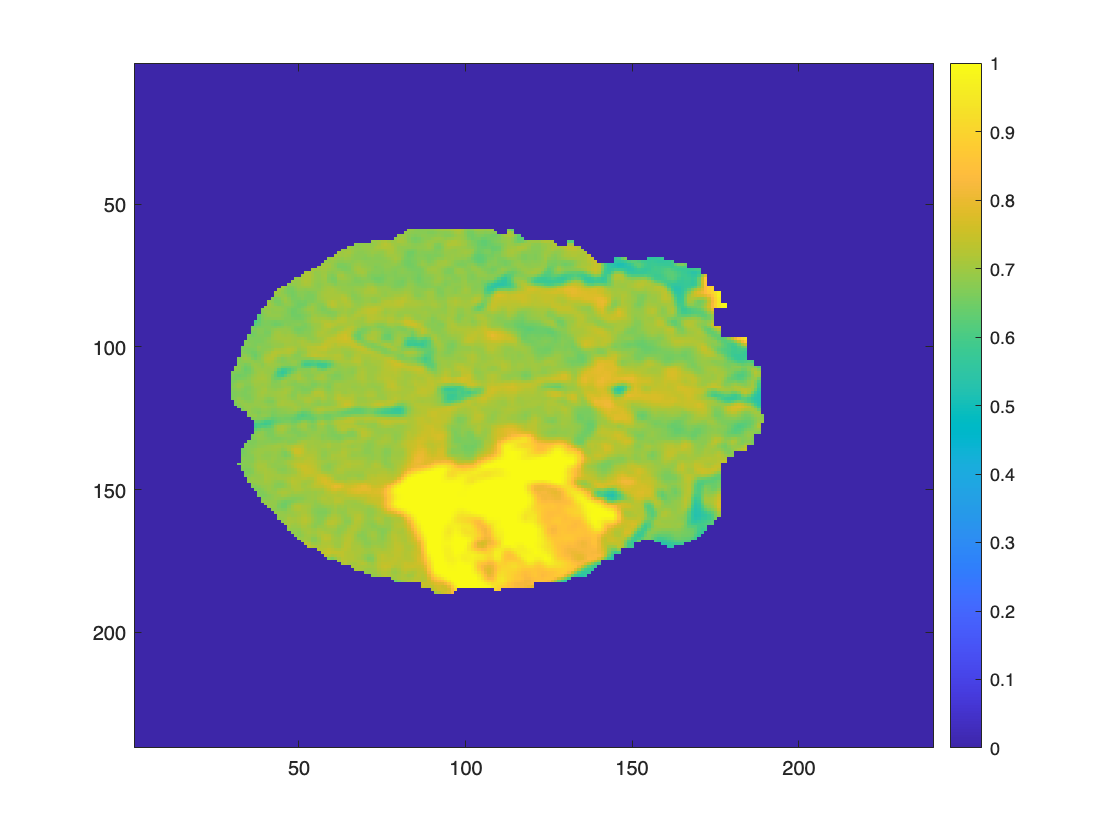

% Apply the sliding window
data_geomean = colfilt(data, window_dim, 'sliding', @geomean);

% Normalization 
norm_geomean = norm_f(data_geomean);

% Visualization 
imagesc(norm_geomean)
colorbar;

### Obtain the segmented image with Mamdani

Mamdani Fuzzy Inference System is a fuzzy logic system originally introduced to create control systems with linguistic terms.

The main components are:

- Fuzzification, used to convert inputs into fuzzy sets and based on membership functions;

- Inference engine, used to combine and apply fuzzy logic rules to obtain a fuzzy output;

- Defuzzification, used to convert the obtained fuzzy output into a crisp value. 

The output of each rule is a fuzzy set and the fuzzy sets obtained for each rule are aggregated (through different methods) to obtain a single output. The obtained output is then defuzzified.

We defined the Mamdani FIS in the GUI of the Fuzzy Logic Toolbox.

We started by defining the membership functions for each feature (input) and for the output and then we defined the fuzzy rules used to obtain the output. 

The fis file contains all the features with their membership functions and the rules to obtain the output (tumor or not tumor).

% Read the fis file
mam_fis = readfis('mam_Segmentation.fis');

Initialize a zero matrix for the mamdani scores.

% Define the dimensions of the original image
dimX = size(data, 1);
dimY = size(data, 2);

% Initialize a zero matrix
mam_scores = zeros(dimX, dimY);

Scan each pixel to obtain the segmented image.

Evaluated the defined FIS for each pixel to classify them as tumor or not.

% Scan the image pixel by pixel
for i = 1 : dimY
    for j = 1 : dimX
        % Evaluate the Mamdani FIS for each pixel using all the defined features 
        mam_scores(i,j) = evalfis(mam_fis, [ ...
            norm_data(i,j) ...
            norm_mean(i,j) ...
            norm_std(i,j) ...
            norm_kurtosis(i,j) ...
            norm_skewness(i,j) ...
            norm_entropy(i,j) ...
            norm_energy(i,j) ...
            norm_contrast(i,j) ...
            norm_median(i,j) ...
            norm_harmmean(i,j) ...
            norm_geomean(i,j) ...
            ]);
    end
end

Normalize the image to be in range [0 1]

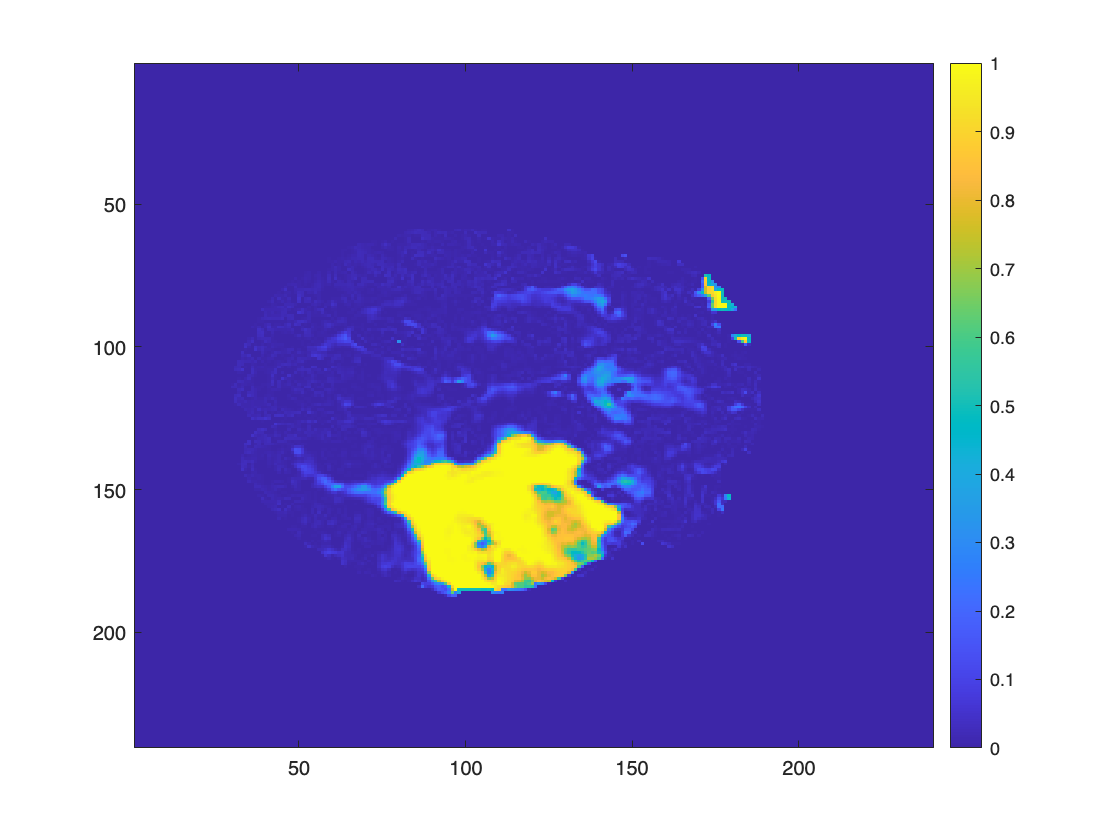

% Normalization
mam_scores = norm_f(mam_scores);

% Visualization 
imagesc(mam_scores)
colorbar;

After applying the Mamdani FIS we obtain the image above, which shows the areas where the tumor is present (higher values). 

### Get the tumor mask

Find the area where the tumor is present, i.e. the mask.

To get the mask we set a threshold of 0.75, which means that only the pixels with intensity grater than 0.75 will be identified as tumor.

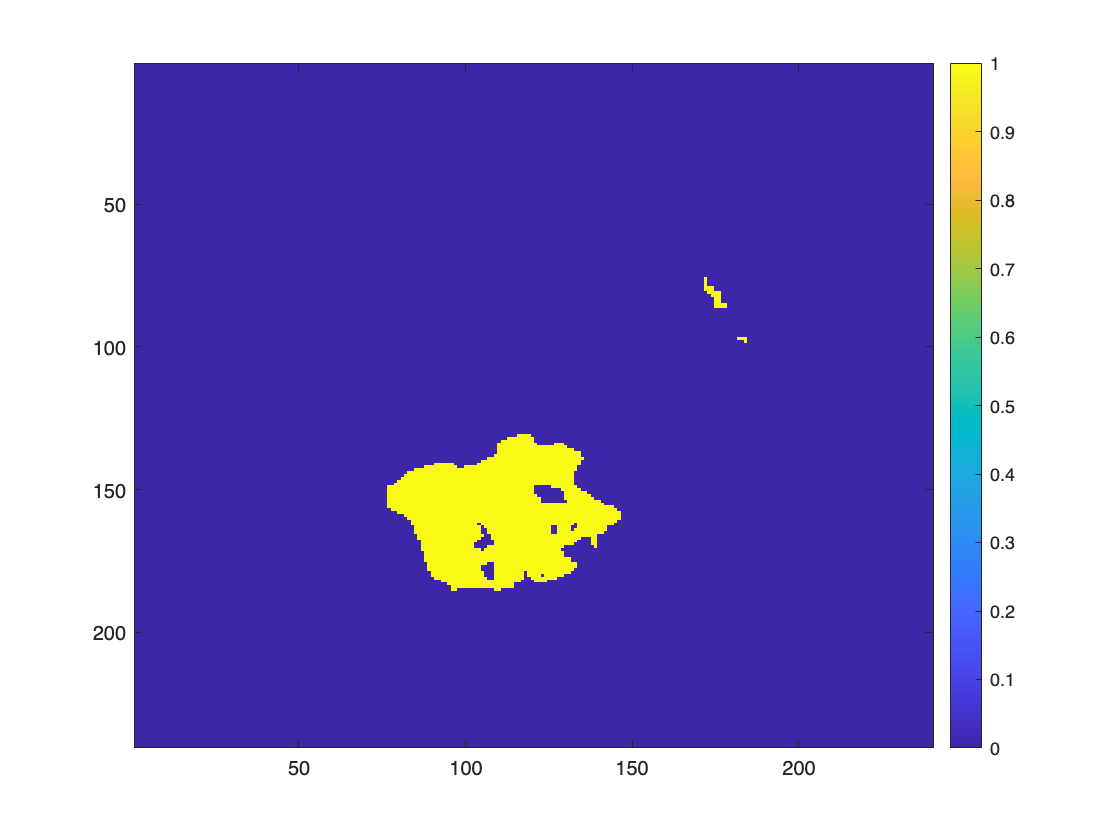

mam_mask = mam_scores > 0.75;

% Visualize
imagesc(mam_mask)
colorbar;

The obtained image shows the area where the tumor is present. 

We can distinguish where the tumor is present (1) and there it is not present (0), this means that the rules defined in the Mamdani FIS has been applied correctly.

### Obtain the segmented image with Sugeno

Sugeno Fuzzy Inference System is another type of fuzzy logic system, similar to the Mamdani system.

The main difference between the two type of systems is that Sugeno uses singleton output membership functions (linear or constant) that won't need defuzzification since the output is already a crisp value. All the other main components remains the same.

To pass from the Mamdani FIS to the Sugeno FIS we used 'Mamdani to Sugeno' in the GUI of the Fuzzy Logic Toolbox.

The fis file contains all the features with their membership functions and the rules to obtain the output (tumor or not tumor).

% Read the FIS file
sug_fis = readfis('sug_Segmentation.fis');

% Initialize a zero matrix
sug_scores = zeros(dimX, dimY);

Scan the image pixel by pixel.

Evaluated the defined FIS for each pixel to classify them as tumor or not.

% Scan the image pixel by pixel
for i = 1 : dimY
    for j = 1 : dimX
        % Evaluate the Sugeno FIS for each pixel using all the defined features 
        sug_scores(i,j) = evalfis(sug_fis, [ ...
            norm_data(i,j) ...
            norm_mean(i,j) ...
            norm_std(i,j) ...
            norm_kurtosis(i,j) ...
            norm_skewness(i,j) ...
            norm_entropy(i,j) ...
            norm_energy(i,j) ...
            norm_contrast(i,j) ...
            norm_median(i,j) ...
            norm_harmmean(i,j) ...
            norm_geomean(i,j) ...
            ]);
    end
end

Normalize the image to be in range [0 1]

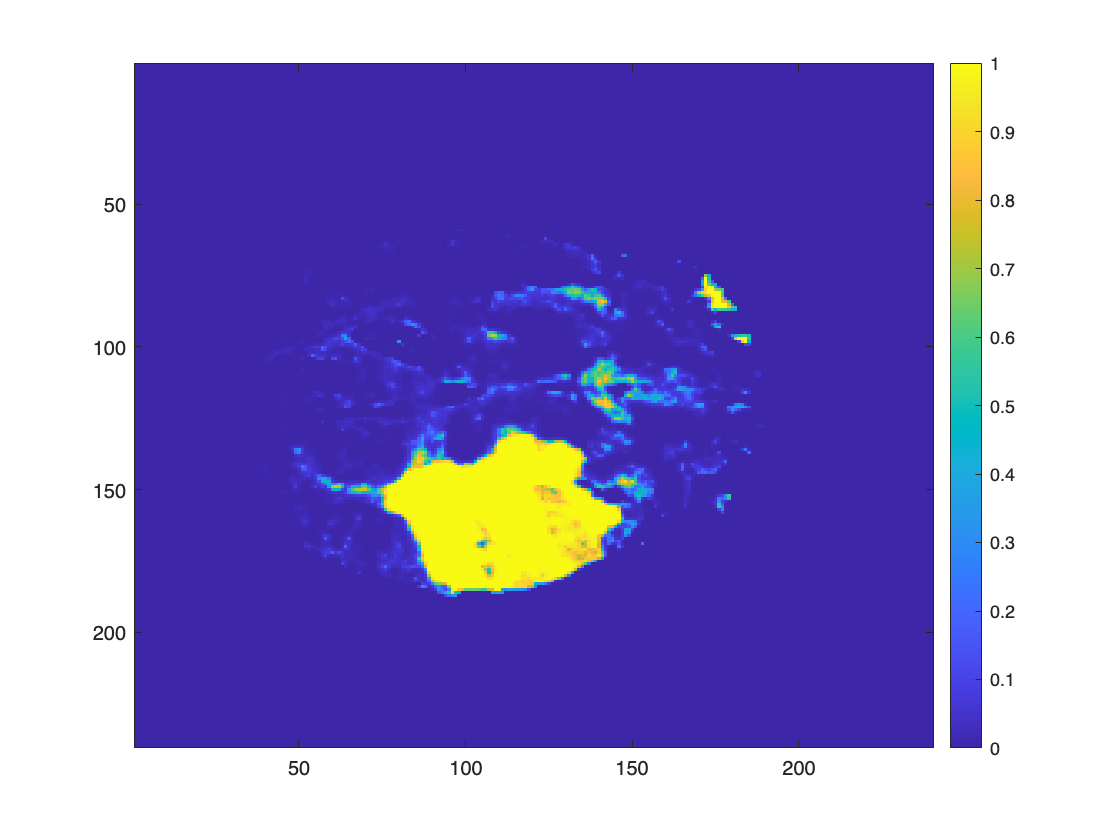

% Normalization
sug_scores = norm_f(sug_scores);

% Visualization 
imagesc(sug_scores)
colorbar;

After applying the Sugeno FIS we obtain the image above, which shows the areas where the tumor is present (higher values). 

### Get the tumor mask

Find the area where the tumor is present, i.e. the mask.

To get the mask we set a threshold of 0.75, which means that only the pixels with intensity grater than 0.75 will be identified as tumor.

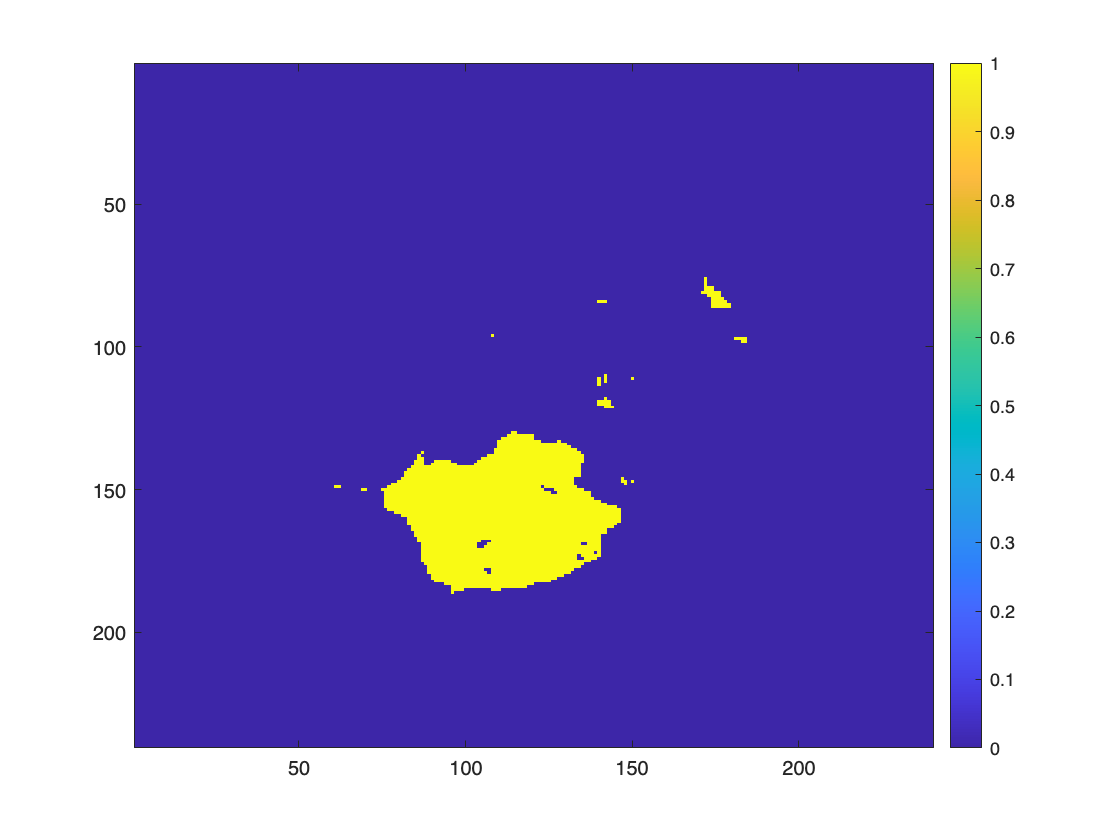

sug_mask = sug_scores > 0.75;

% Visualize
imagesc(sug_mask)
colorbar;

The obtained image shows the area where the tumor is present. 

We can distinguish where the tumor is present (1) and there it is not present (0), this means that the rules defined in the Mamdani FIS has been applied correctly.

We can see that it is similar, but not equal, to the golden standard so we will apply a genetic algorithm to adjust the rules' weights to obtain a better results.

Throughout the project we will use the Sugeno FIS. We chose to use Sugeno since it returns crisp outputs which are more adjustable with weight and thus, this makes it more suitable for rule weights tuning using a genetic algorithm. We should also consider that the Sugeno system is more computationally efficient and work better with optimization. 

## PHASE 2: Genetic Algorithm for Rule Weights Tuning

The aim of the Genetic Algorithm is to identify the best combination of rule weight to be used for the tumor segmentation.

Find the best rule weights' combination is important to obtain a better result in the segmentation, i.e. obtain a mask as close as possible to the gold standard (*label*).

### Load the fis

base_fis = sug_fis;

% Find the number of rules
num_rules = length(base_fis.rule);

% Visualize the rules
sug_rules = base_fis.Rules()

sug_rules =   1×44 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                                                                                          Description                                                                                
          ___________________________________________________________________________________________________________________________________________________________________________

    1     "pixel==tumor & mean==tumor => output=tumor (1)"                                                                                                                           
    2     "pixel==tumor & energy==tumor => output=tumor (1)"                                                                                                                         
 

### Define initial population

The initial population is composed by a fixed number of individuals (chromosomes).

Each individual is a vector containing the weights of each rule defined in the FIS.

In the intial population the weights are set at random with values between 0 and 1.

The population is a matrix (population size x number of rules) in which each row is an individual containing the weights of the FIS rules.

% Set the size of the population
size_population = 8;

% Define random weights between 0 and 1 
population = rand(size_population, num_rules);

Define the features

features = { ...
            norm_data ...
            norm_mean ...
            norm_std ...
            norm_kurtosis ...
            norm_skewness ...
            norm_entropy ...
            norm_energy ...
            norm_contrast ...
            norm_median ...
            norm_harmmean ...
            norm_geomean ...
            };

label_mask = label;

### Define the fitness function (this section takes a long time to run)

The fitness function is defined in the file '*fitnessFunction.m*'.

fitnessFunction = @(w) fitnessFunction(w, base_fis, features, label_mask);

Define the upper and lower bound.

The lower bound is 0 and the upper bound is 1 becuase the rule weights must be in range [0 1].

lb = zeros(1, num_rules);
ub = ones(1, num_rules);

### Genetic Algorithm

Define the variables

population_range = [0; 1];
population_size = size(population, 1);
max_generations = 40;
max_stall_gen = 10;
fit_limit = 270;
cross_fraction = 0.6;
elite_count = 1;

Define the genetic algorithm options


Single objective optimization:
44 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionroulette
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1               16             291             367        0
    2               23             291           373.5        1
    3               30             289             352        0
    4               37             284           300.5        0
    5               44             284           288.1        1
    6               51             281           287.9        0
    7               58             281           287.9        1
    8               65             281           289.8        2
    9               72             281           288.5        3
   10               79             278           290.4        0
   11        

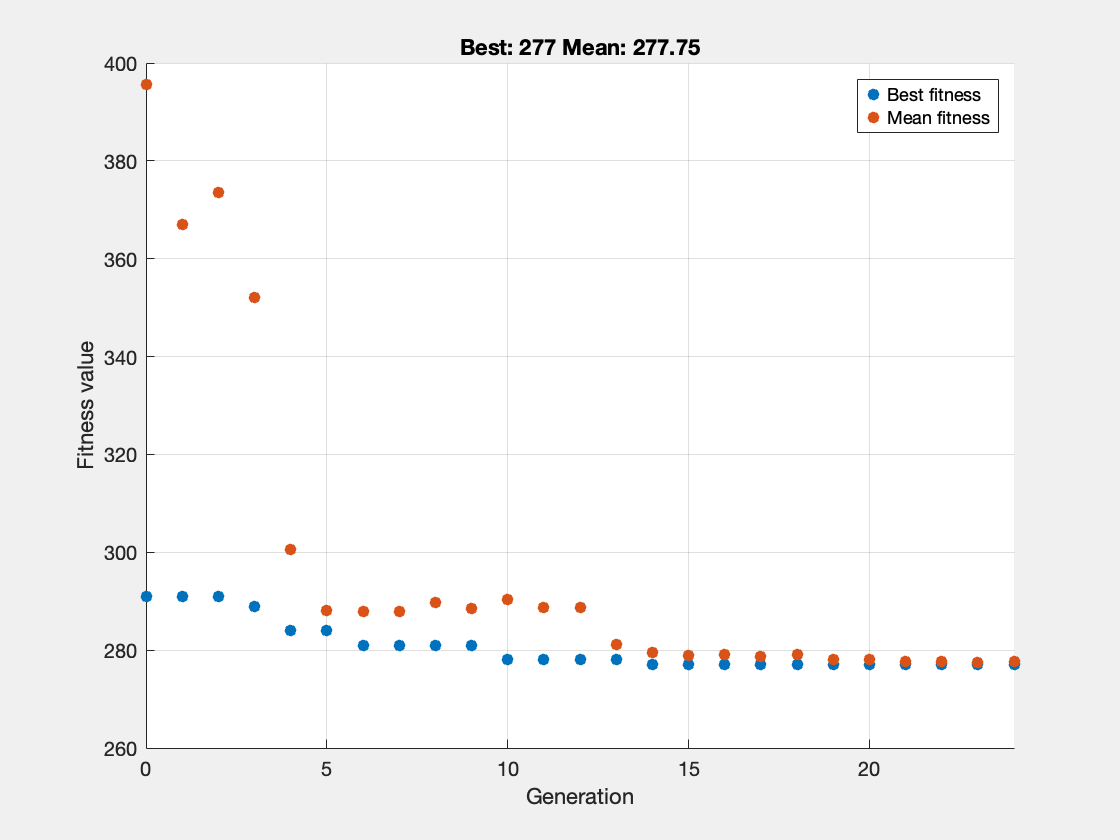

options = optimoptions('ga', ...
    'InitialPopulationMatrix', population, ...
    'InitialPopulationRange', population_range, ...
    'SelectionFcn', 'selectionroulette', ...
    'PopulationSize', population_size, ...
    'MaxGenerations', max_generations, ...  
    'MaxStallGenerations', max_stall_gen, ...
    'FitnessLimit', fit_limit, ...
    'CrossoverFraction', cross_fraction, ...
    'MutationFcn', 'mutationadaptfeasible', ...
    'EliteCount', elite_count, ...
    'Display', 'iter', ...
    'UseParallel', false, ...
    'PlotFcn', {@gaplotbestf});

% Run GA
[best_weights, best_fit] = ga(fitnessFunction, num_rules, [], [], [], [], lb, ub, [], options);

Once we obtained the best combination of weights for the rules ('*best_weights*'), we apply them to a new Fuzzy Inference System called '*opt_fis*'.

The optmized FIS has the same inputs, membership functions as rules as the Sugeno FIS and the rule weights are the best weights obtained through Genetic Algorithm.

% Apply optimized weights to the FIS
opt_fis = base_fis;
for i = 1:num_rules
    opt_fis.rule(i).weight = best_weights(i);
end

% Create a new FIS to store the result
writefis(opt_fis, 'opt_Segmentation.fis');

% Display the best fit (the number of misclassified pixels)
best_fit

best_fit = 277

best_fit = 277 tells us that only 277 pixels were misclassified in the image. This indicates that the system is working well.

### Evaluate the optimized FIS 

We want to visualize the tumor mask after applying the genetic algorithm.

Do the same as before to visualize the image and visualize the mask.

% Read the FIS file
opt_fis = readfis('opt_Segmentation.fis');

% Initialize a zero matrix for the scores
opt_scores = zeros(dimX, dimY);

% Scan the image pixel by pixel
for i = 1 : dimY
    for j = 1 : dimX
        % Evaluate the optimized Sugeno FIS for each pixel using all the defined features 
        opt_scores(i,j) = evalfis(opt_fis, [ ...
            norm_data(i,j) ...
            norm_mean(i,j) ...
            norm_std(i,j) ...
            norm_kurtosis(i,j) ...
            norm_skewness(i,j) ...
            norm_entropy(i,j) ...
            norm_energy(i,j) ...
            norm_contrast(i,j) ...
            norm_median(i,j) ...
            norm_harmmean(i,j) ...
            norm_geomean(i,j) ...
            ]);
    end
end

% Normalization
opt_scores = norm_f(opt_scores);

% Visualization 
imagesc(opt_scores)
colorbar;

To get the mask we set a threshold of 0.75, which means that only the pixels with intensity grater than 0.75 will be identified as tumor.

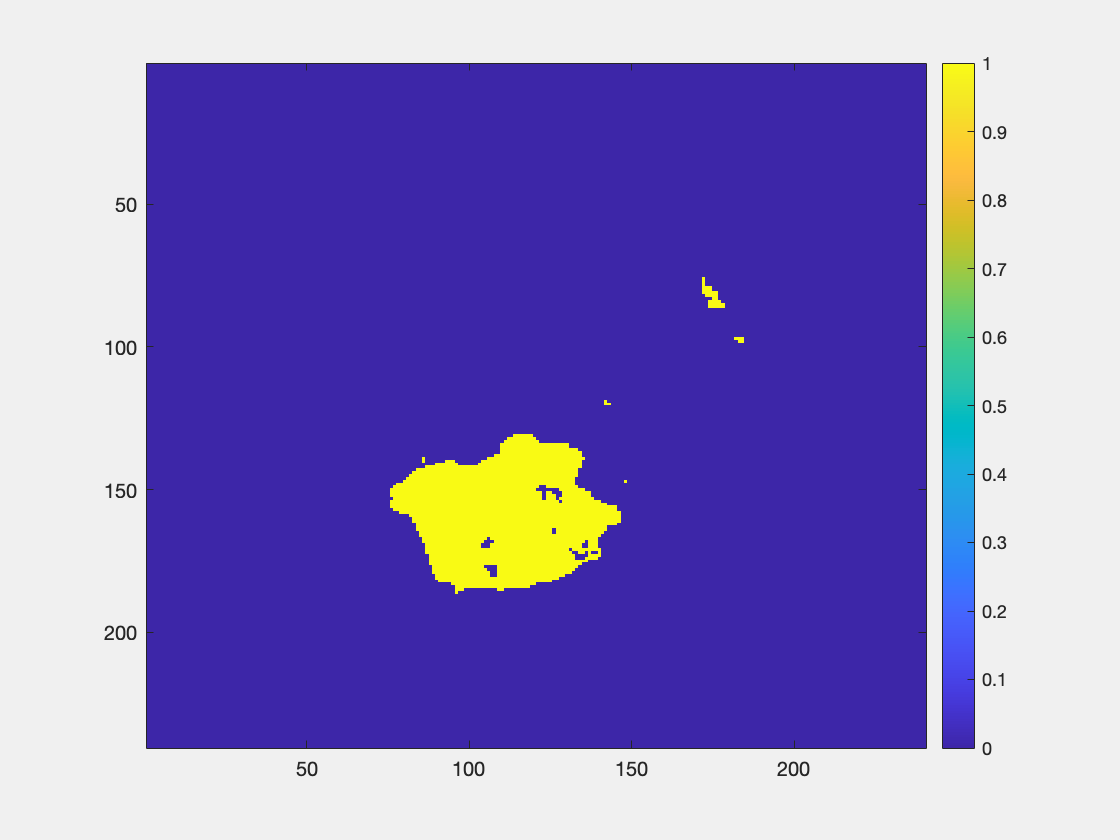

opt_mask = opt_scores > 0.75;

% Visualize
imagesc(opt_mask)
colorbar;

We can observe that the mask is better than the one obtained before the weight tuning but it is still not perfect.

## PHASE 3: Evaluation of the Results

Test the system on a second image that the system has never seen.

We do this to evaluate how well the system can generalize.

### Download a second image

Download a second image to test the system.

test_dataFileName = fullfile(imageDir, "BraTS446");
test_labelFileName = fullfile(labelDir, "BraTS446");

Load the data of a different patient.

test_data = load(test_dataFileName); 
test_label = load(test_labelFileName);

Extract a slice out of a 3D image.

sliceNumber = 70;
test_data = test_data.cropVol(:,:,sliceNumber,1);  
test_label = test_label.cropLabel(:,:,sliceNumber);

Visualize the image 

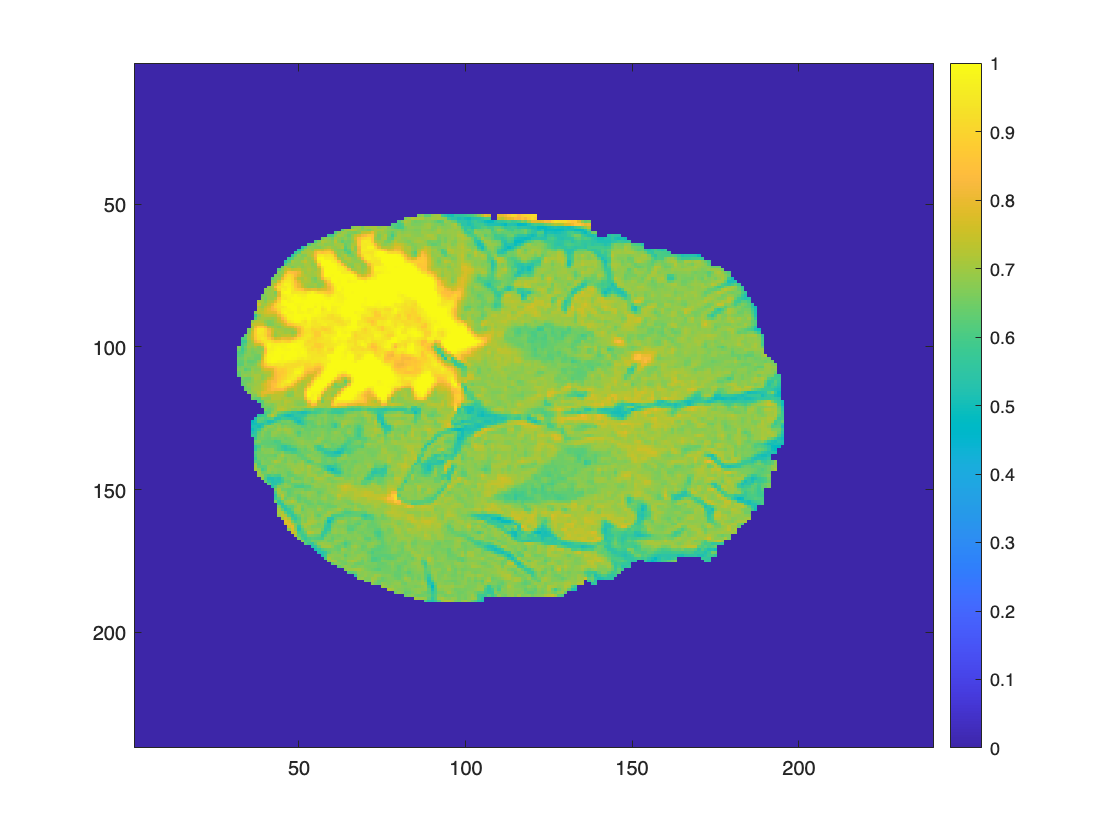

imagesc(test_data)
colorbar;

Normalize

test_norm_data = norm_f(test_data);

Visualize the mask

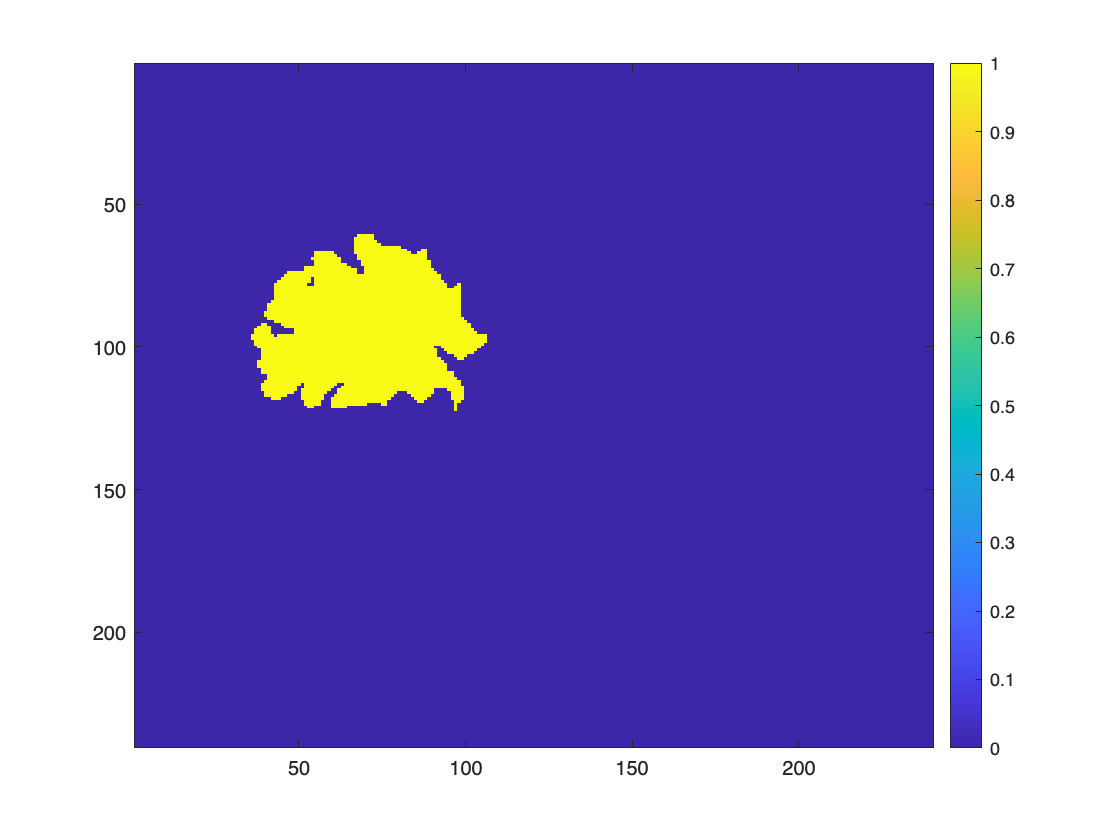

imagesc(test_label)
colorbar;

### Define the features

Define all the features that are used in the Fuzzy Inference System for the test image and normalize them.

% Mean
test_data_mean = colfilt(test_data, window_dim, 'sliding', @mean);
test_norm_mean = norm_f(test_data_mean);

% Standard deviation
test_data_std = colfilt(test_data, window_dim, 'sliding', @std);
test_norm_std = norm_f(test_data_std);

% Kurtosis
test_data_kurtosis = colfilt(test_data, window_dim, 'sliding', @kurtosis);
test_data_kurtosis = fillmissing(test_data_kurtosis, 'constant', 0);
test_norm_kurtosis = norm_f(test_data_kurtosis);

% Skewness
test_data_skewness = colfilt(test_data, window_dim, 'sliding', @skewness);
test_data_skewness = fillmissing(test_data_skewness, 'constant', 0);  
test_norm_skewness = norm_f(test_data_skewness);

% Entropy
test_data_entropy = entropyfilt(test_data);
test_norm_entropy = norm_f(test_data_entropy);

% Energy
test_data_energy = colfilt(test_data, window_dim, 'sliding', energy_f);
test_norm_energy = norm_f(test_data_energy);

% Contrast
test_data_contrast = imadjust(test_data);
test_norm_contrast = norm_f(test_data_contrast);

% Median
test_data_median = colfilt(test_data, window_dim, 'sliding', @median);
test_norm_median = norm_f(test_data_median);

% Harmonic mean
test_data_harmmean = colfilt(test_data, window_dim, 'sliding', @harmmean);
test_norm_harmmean = norm_f(test_data_harmmean);

% Geometric mean
test_data_geomean = colfilt(test_data, window_dim, 'sliding', @geomean);
test_norm_geomean = norm_f(test_data_geomean);

### Evaluate the optimized FIS on the test image

We evaluate every pixel of the test image with the optimized FIS. In this way we can identify the area where the tumor is present. 

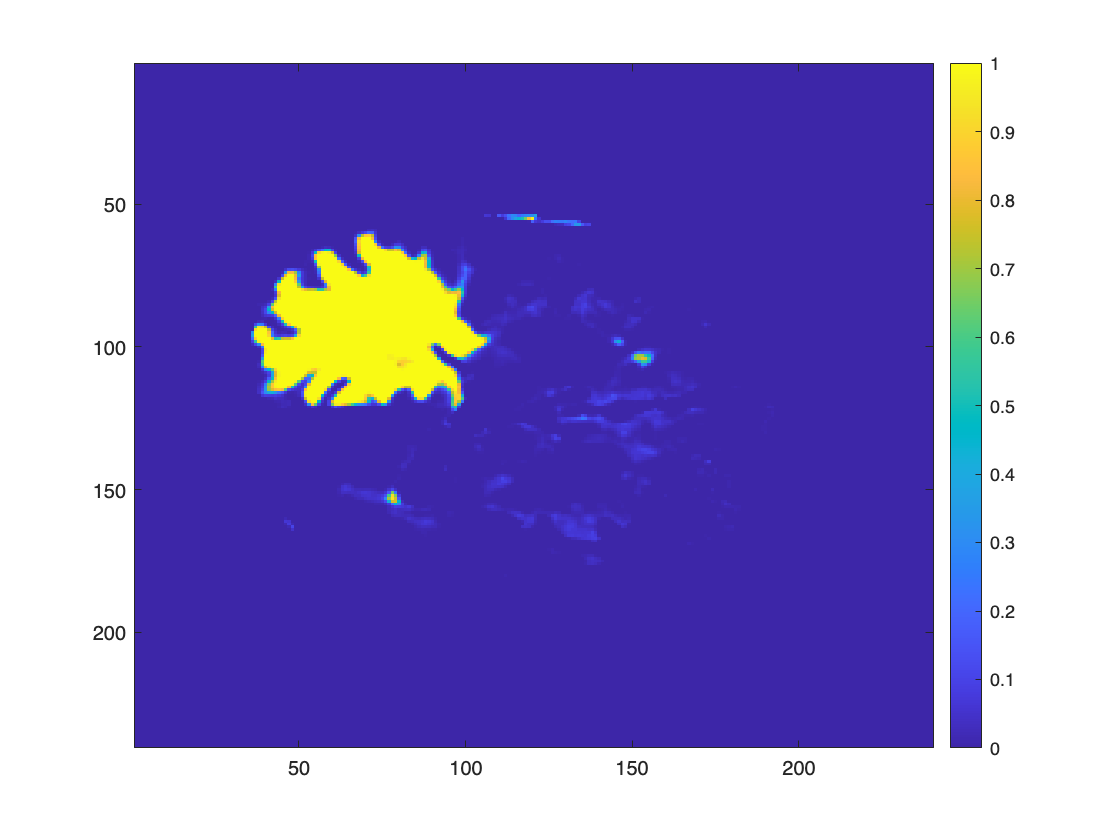

% Initialize a zero matrix for the scores
test_scores = zeros(dimX, dimY);

% Scan the image pixel by pixel
for i = 1 : dimY
    for j = 1 : dimX
        % Evaluate the optimized Sugeno FIS for each pixel using all the defined features 
        test_scores(i,j) = evalfis(opt_fis, [ ...
            test_norm_data(i,j) ...
            test_norm_mean(i,j) ...
            test_norm_std(i,j) ...
            test_norm_kurtosis(i,j) ...
            test_norm_skewness(i,j) ...
            test_norm_entropy(i,j) ...
            test_norm_energy(i,j) ...
            test_norm_contrast(i,j) ...
            test_norm_median(i,j) ...
            test_norm_harmmean(i,j) ...
            test_norm_geomean(i,j) ...
            ]);
    end
end

% Normalization
test_scores = norm_f(test_scores);

% Visualization 
imagesc(test_scores)
colorbar;

Find the area where the tumor is present, i.e. the mask.

To get the mask we set a threshold of 0.75, which means that only the pixels with intensity grater than 0.75 will be identified as tumor.

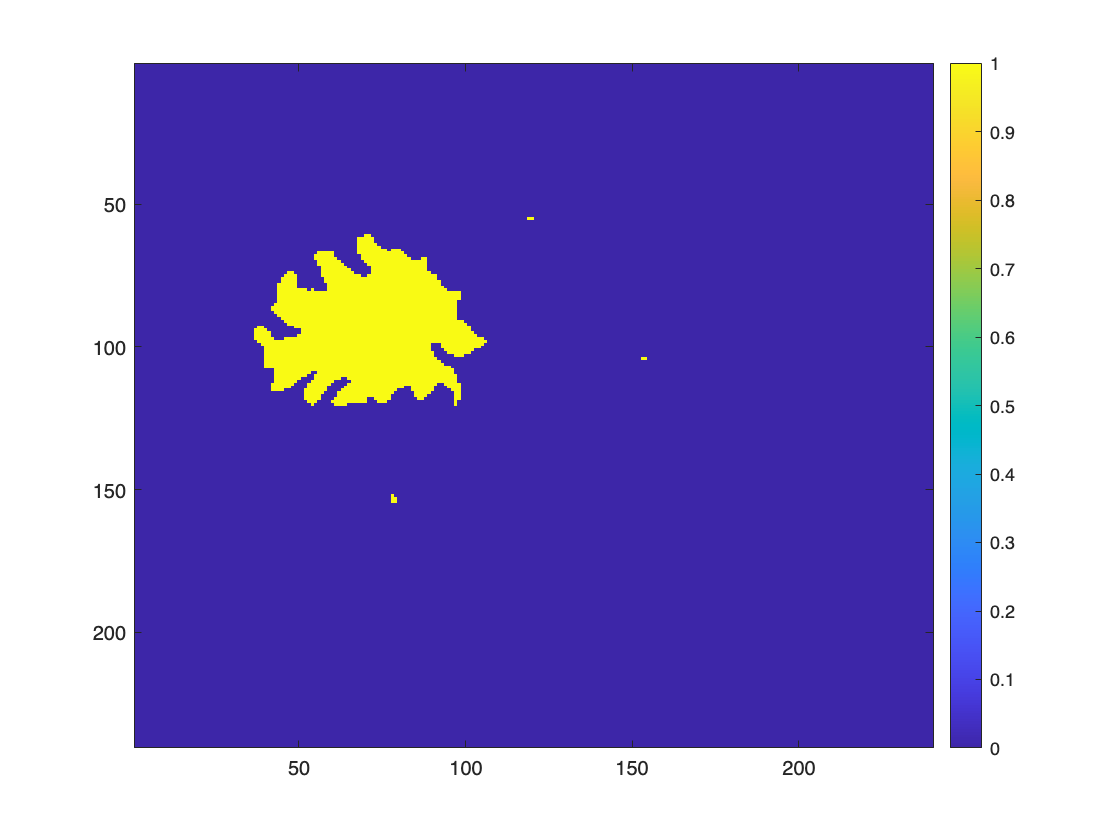

test_mask = test_scores > 0.75;

% Visualize
imagesc(test_mask)
colorbar;

### Evaluate the system

Evaluate the system with the following metrics: 

- Dice: statistical method used to measure the similarity between two sets. 

- Accuracy: fraction of correctly classified pixels

#### Accuracy score

Calculate the Accuracy score for the train image

train_accuracy = sum(label == opt_mask,'all')/numel(opt_mask)

train_accuracy = 0.9944

Calculate the Accuracy score for the test image

test_accuracy = sum(test_label == test_mask,'all')/numel(test_mask)

test_accuracy = 0.9930

#### Dice score

Dice score for train image

train_intersection = sum(opt_mask(:) & label(:));
train_total = sum(opt_mask(:)) + sum(label(:));
train_dice_score = 2 * train_intersection / (train_total + eps)   

train_dice_score = 0.9394

Dice score for test image

test_intersection = sum(test_mask(:) & test_label(:));
test_total = sum(test_mask(:)) + sum(test_label(:));
test_dice_score = 2 * test_intersection / (test_total + eps)  

test_dice_score = 0.9247

### Visualization

#### Visualize train image

figure;
imwrite(data, 'originalImage.png');
imagesc(data)
colorbar;

Visualize the masks

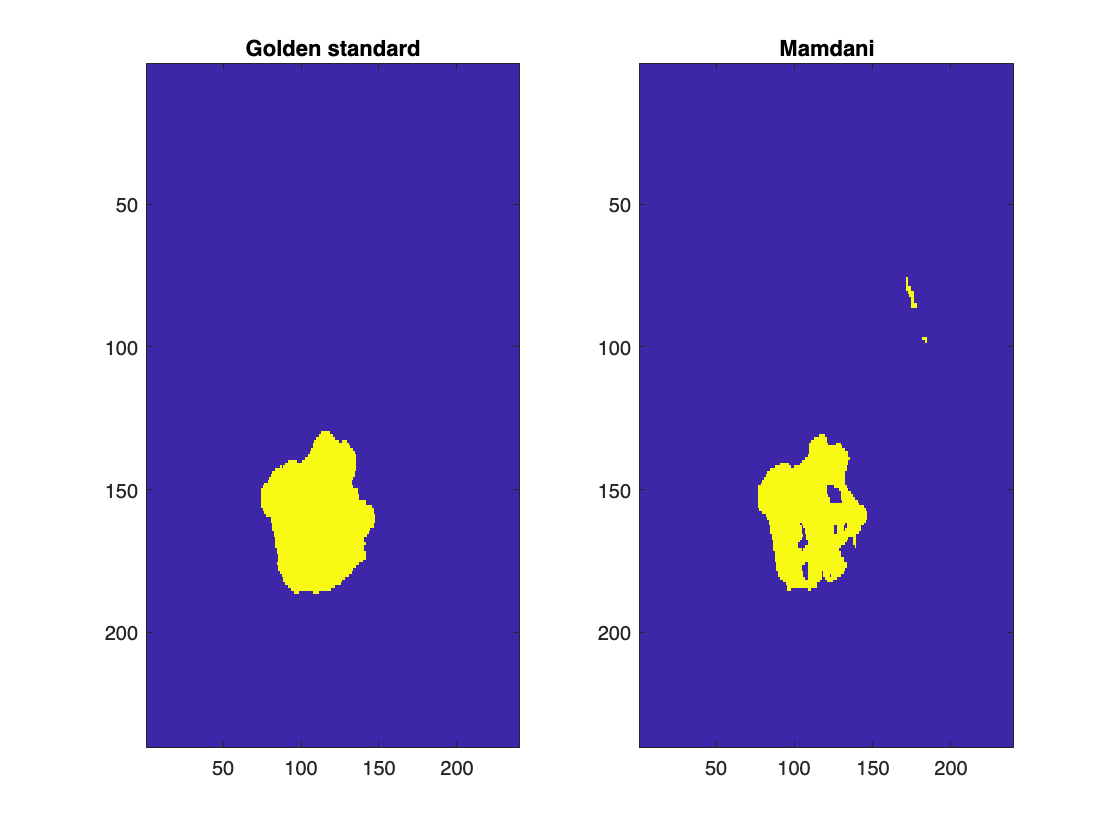

figure;
% Visualize the golden standard
subplot(1, 2, 1);
imwrite(label, 'label_originalImage.png');
imagesc(label)
title('Golden standard');

% Visualize the mask obtain with the Mamdani system
subplot(1, 2, 2);
imwrite(mam_mask, 'mamdani_originalImage.png');
imagesc(mam_mask)
title('Mamdani');

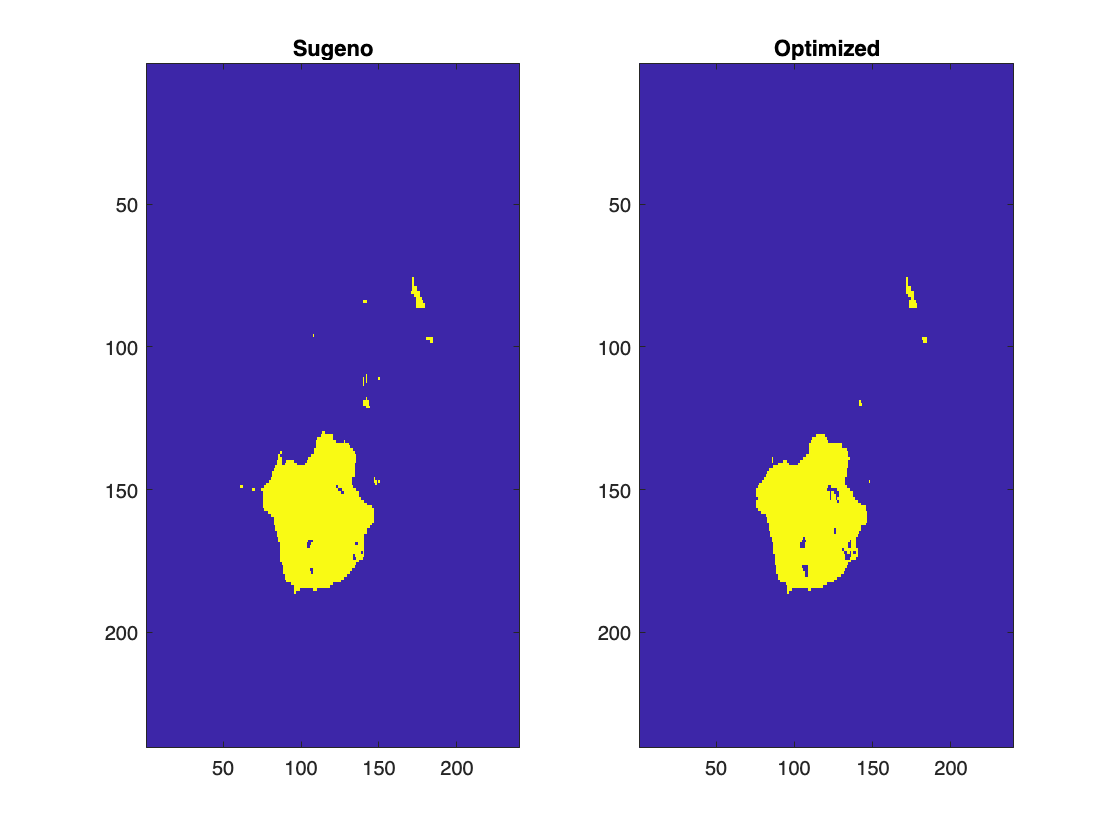

figure;
% Visualize the mask obtain with the Sugeno system
subplot(1, 2, 1);
imwrite(sug_mask, 'sugeno_originalImage.png');
imagesc(sug_mask)
title('Sugeno');

% Visualize the mask obtain with the optimized system
subplot(1, 2, 2);
imwrite(opt_mask, 'optimized_originalImage.png');
imagesc(opt_mask)
title('Optimized');

#### Visualize test image

figure;
imwrite(test_data, 'testImage.png');
imagesc(test_data)
colorbar;

Visualize the masks

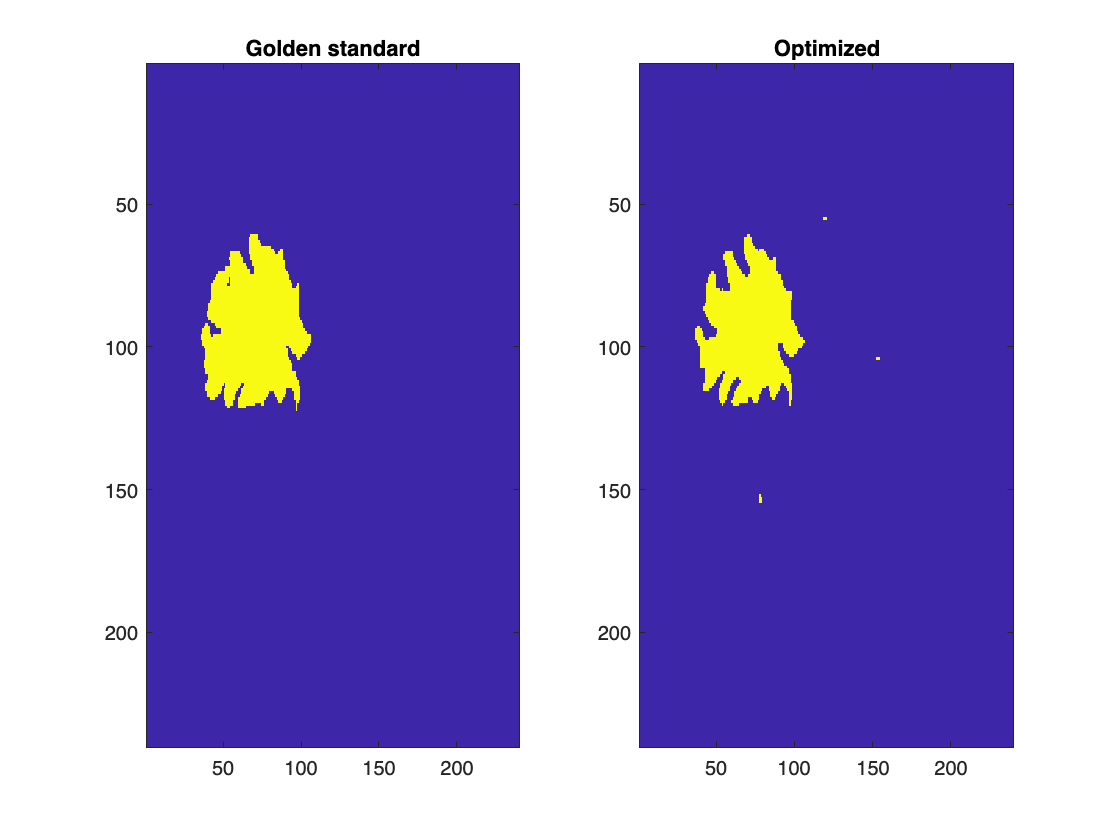

figure;
% Visualize the golden standard
subplot(1, 2, 1);
imwrite(test_label, 'label_testImage.png');
imagesc(test_label)
title('Golden standard');

% Visualize the mask obtain with the optimized system
subplot(1, 2, 2);
imwrite(test_mask, 'optimized_testImage.png');
imagesc(test_mask)
title('Optimized');

By analyzing both the visualizations and the evaluation metrics, we can conclude that the system is performing well on both the train image and the test image. This means that it is able to correctly segment a brain MRI where a tumor is present.